Author: Xiangmin Jiao and Oliver Yang

For further reading, Ch. 12 of [*Attoway*](http://amazon.com/dp/0128154799) and Ch. 9 of [*Lockhart/Tilleson*](http://amazon.com/dp/1630572063) also cover some of the topics of this lecture.

## 2D Plotting

In MATLAB, 2D line plotting uses the `plot` function. In the simpliest case, we can plot an array against its indices:

y = 2 * (1 : 10)

y =      2     4     6     8    10    12    14    16    18    20


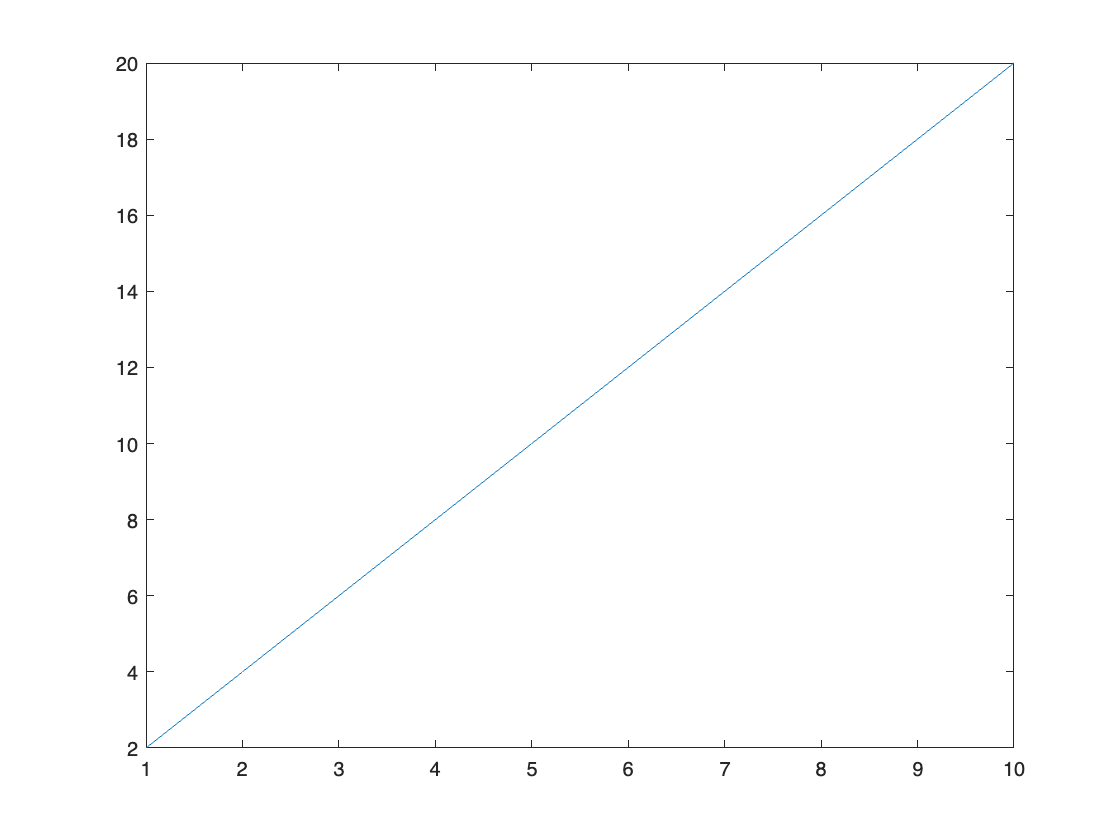

plot(y);

We can specify the $x$-axis by passing in two arrays with the same size.

x = 0 : 0.1 : 1

x =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000


y = 0.5 * x

y =          0    0.0500    0.1000    0.1500    0.2000    0.2500    0.3000    0.3500    0.4000    0.4500    0.5000


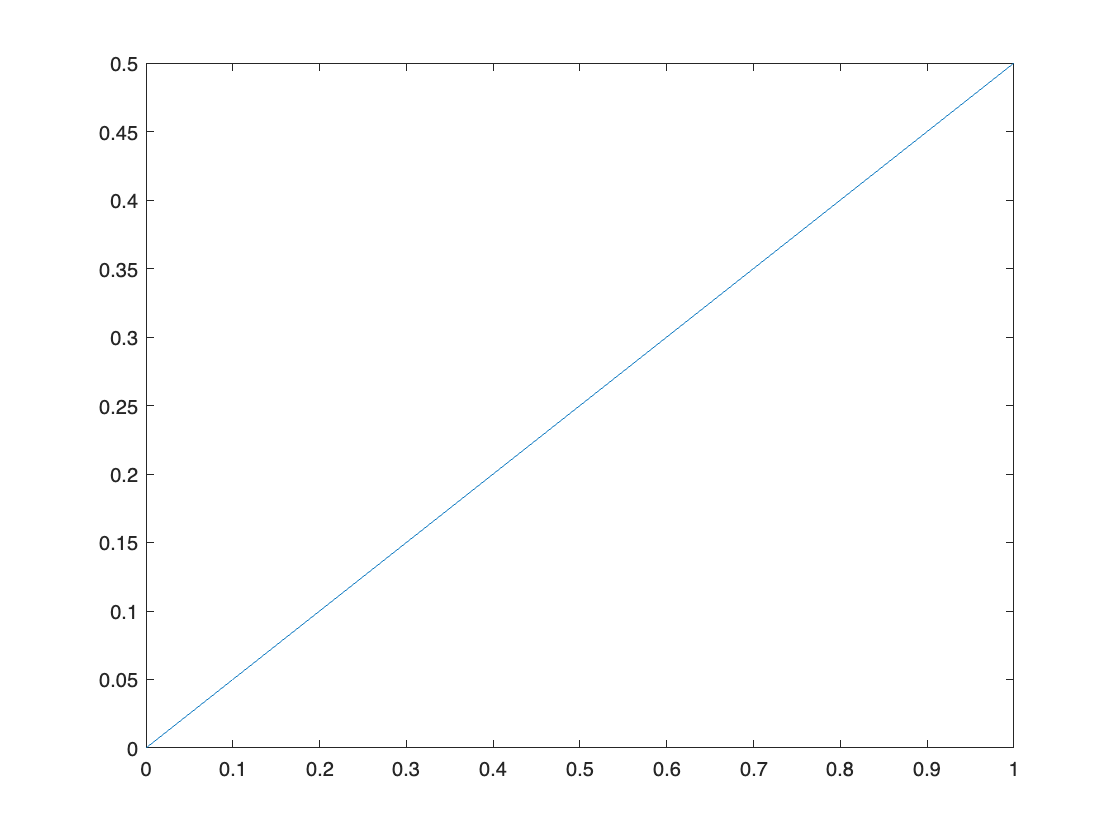

plot(x, y);

We can specify the axis limits and aspect ratios (later) using the `axis` function. For limits, pass in an array containing `[xmin xmax ymin ymax]:`

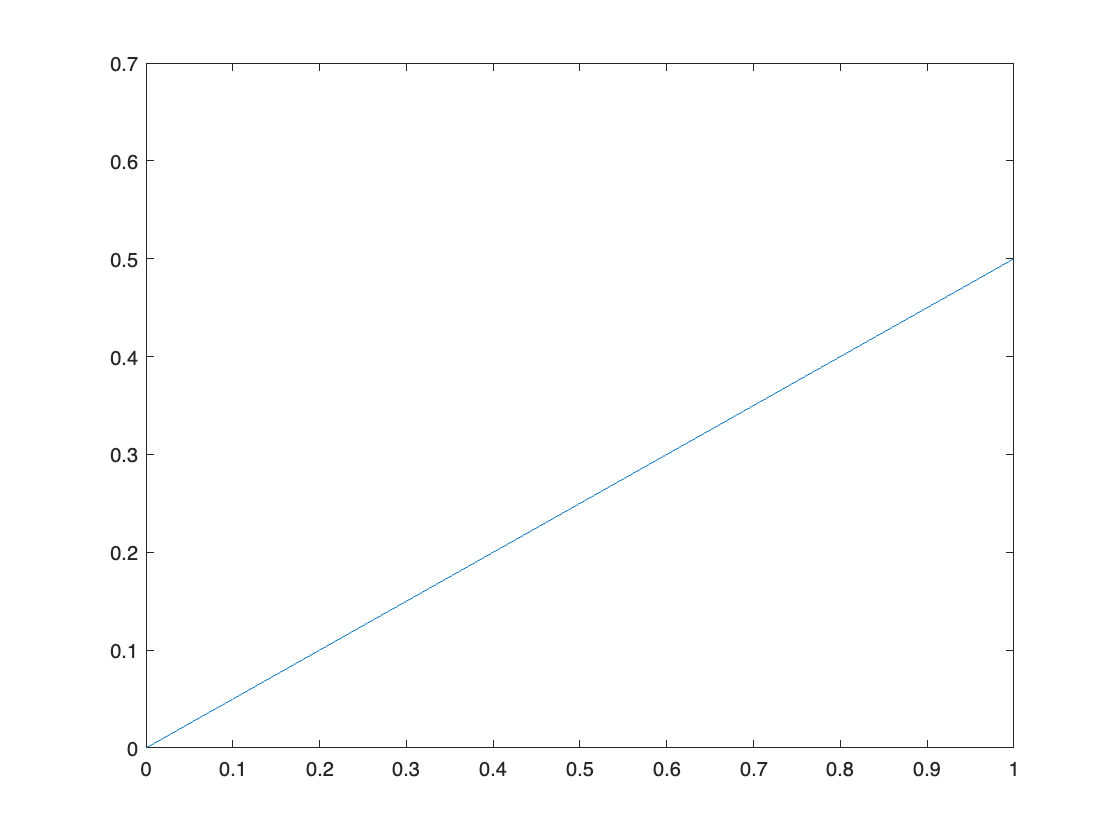

axis([0, 1, 0, 0.7]);

We can also set the limits for the $x$-axis only using the `xlim` function:

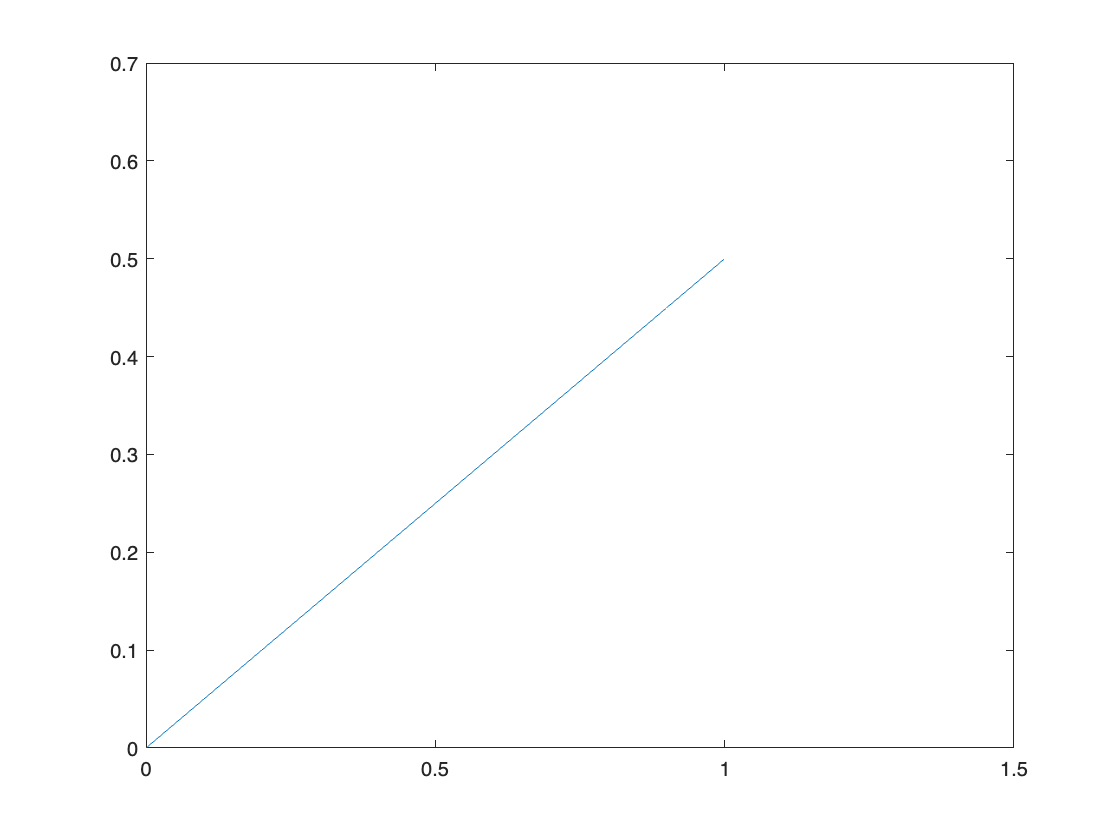

xlim([0, 1.5]);

We can label the $x$ and $y$ axes using the `xlabel` and `ylabel` functions.

x = 0 : pi / 10 : pi

x =          0    0.3142    0.6283    0.9425    1.2566    1.5708    1.8850    2.1991    2.5133    2.8274    3.1416


y = sin(x)

y =          0    0.3090    0.5878    0.8090    0.9511    1.0000    0.9511    0.8090    0.5878    0.3090    0.0000


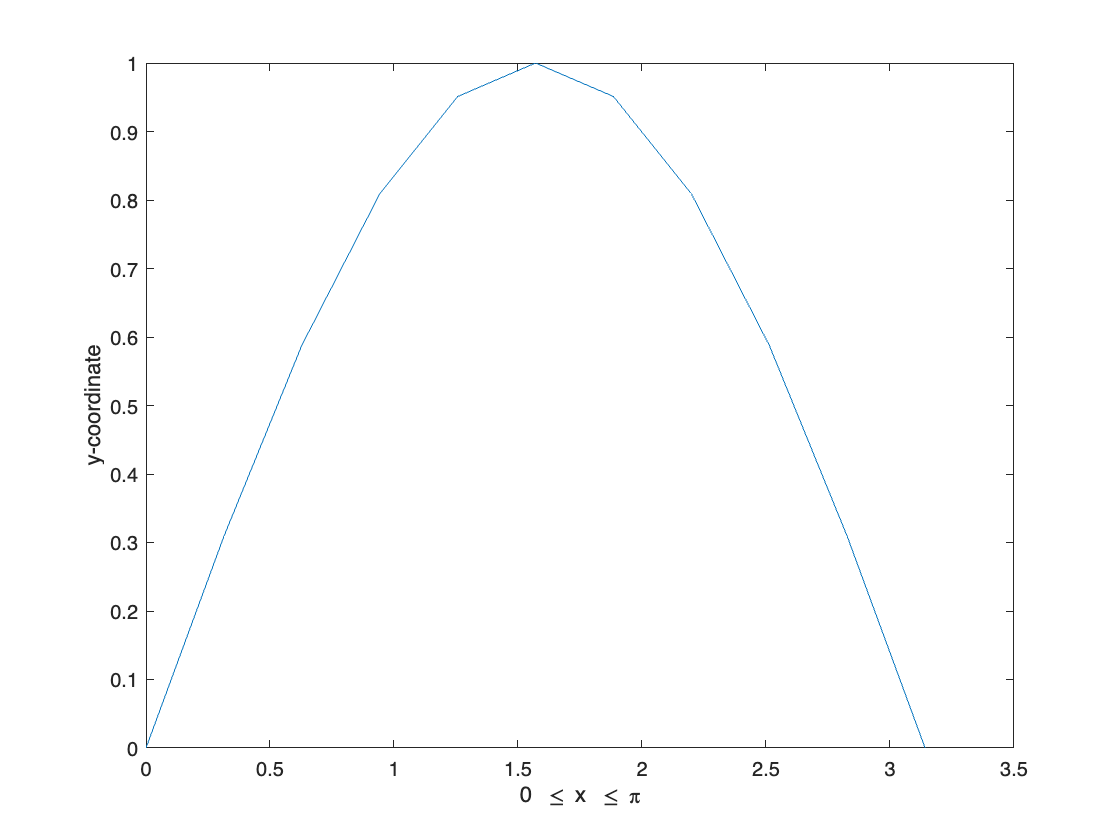

plot(x, y);
xlabel('0 \leq x \leq \pi');
ylabel('y-coordinate');

We can also add a title to a plot using the `title` function. Here, LaTeX commands can be used.

x = 0 : pi / 20 : pi

x =          0    0.1571    0.3142    0.4712    0.6283    0.7854    0.9425    1.0996    1.2566    1.4137    1.5708    1.7279    1.8850    2.0420    2.1991    2.3562    2.5133    2.6704    2.8274    2.9845    3.1416


y = sin(x)

y =          0    0.1564    0.3090    0.4540    0.5878    0.7071    0.8090    0.8910    0.9511    0.9877    1.0000    0.9877    0.9511    0.8910    0.8090    0.7071    0.5878    0.4540    0.3090    0.1564    0.0000


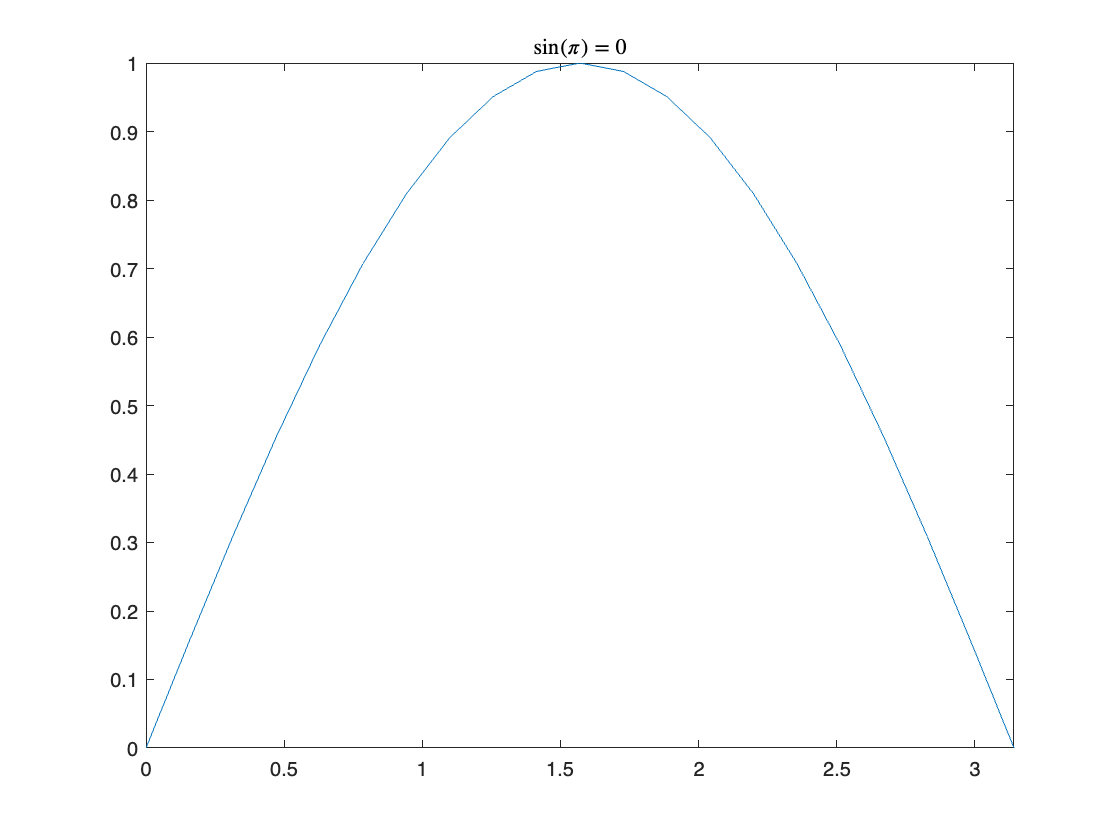

plot(x, y);
xlim([0, pi]);
title('$\sin(\pi) = 0$', 'Interpreter', 'latex');

To annotate a figure, we can add arbitrary text using the `text` function, and use the `legend` function.

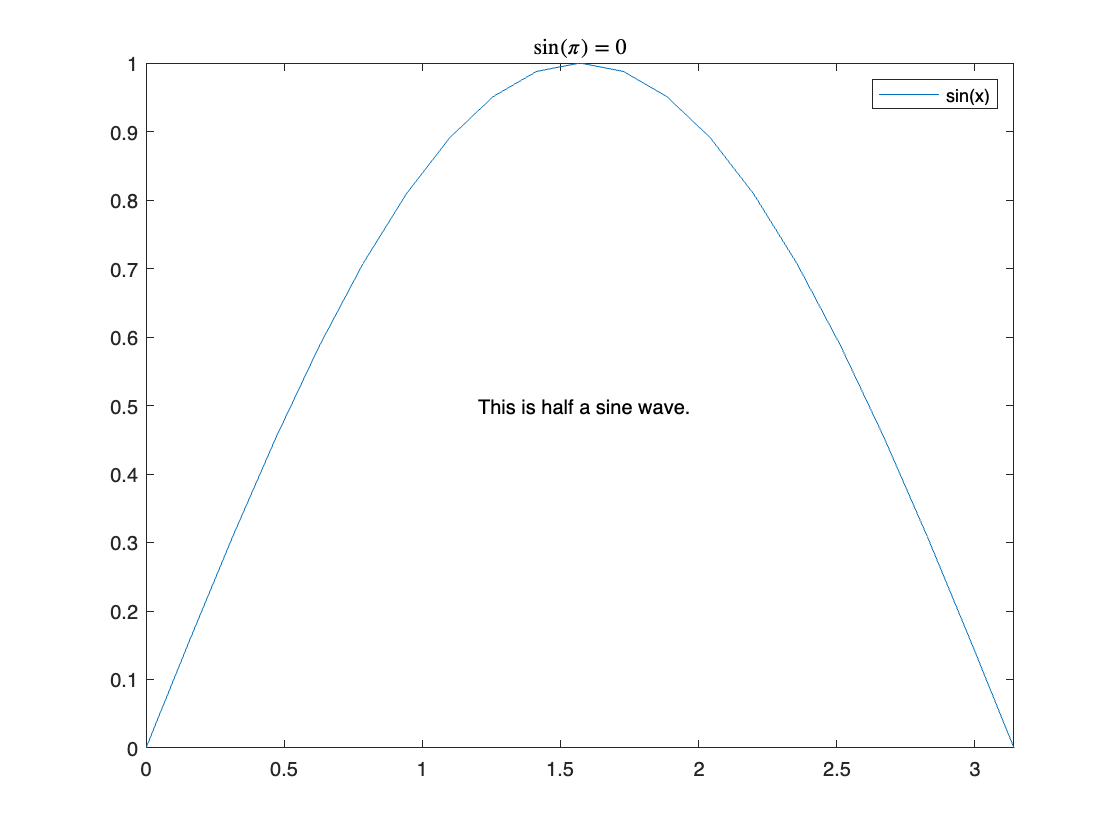

text(1.2, 0.5, 'This is half a sine wave.');
legend('sin(x)');

Multiple $x$-$y$ pairs can be plotted by listing them consecutively in the input argument to the `plot` function and specify their legends using the `legend` function.

y2 = cos(x)

y2 =     1.0000    0.9877    0.9511    0.8910    0.8090    0.7071    0.5878    0.4540    0.3090    0.1564    0.0000   -0.1564   -0.3090   -0.4540   -0.5878   -0.7071   -0.8090   -0.8910   -0.9511   -0.9877   -1.0000


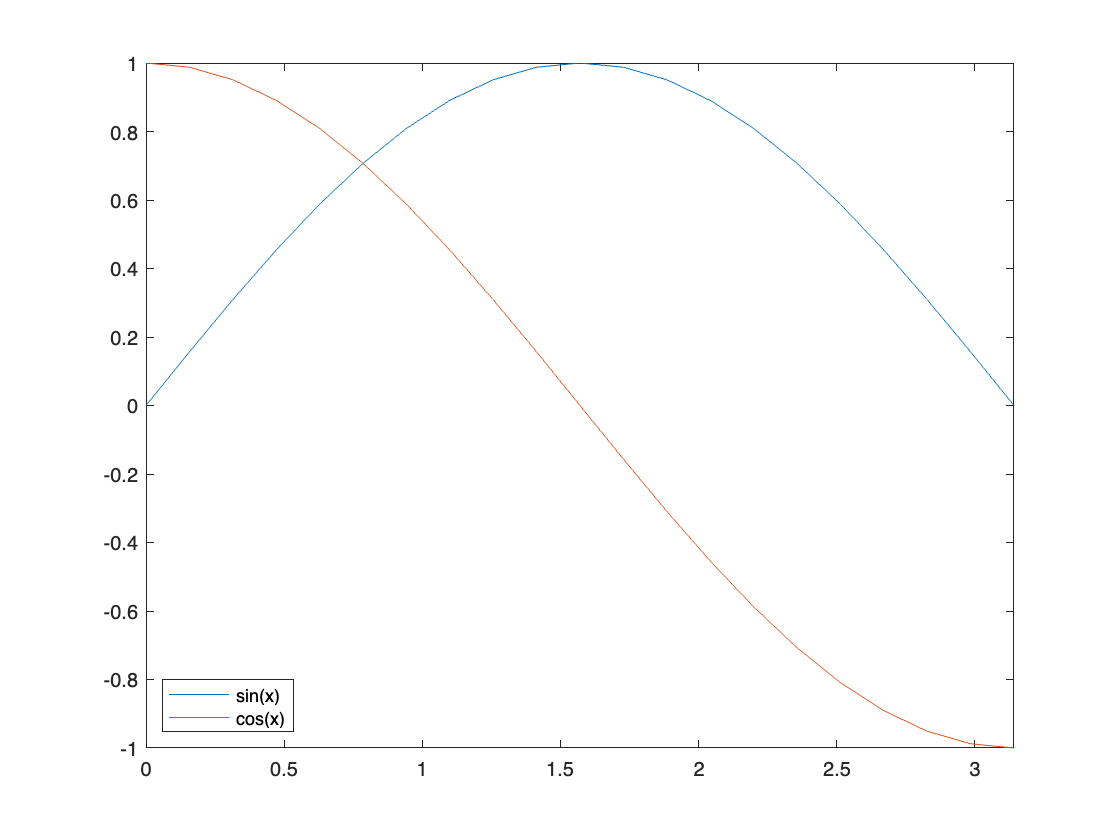

plot(x, y, x, y2);
xlim([0, pi]);
legend('sin(x)', 'cos(x)', 'location', 'SouthWest');

If we wish to use multiple `plot` functions in the same figure, we need to use the `hold` function to retain the figure. 

In this case, we want to use different colors, line styles, and markers for different curves.

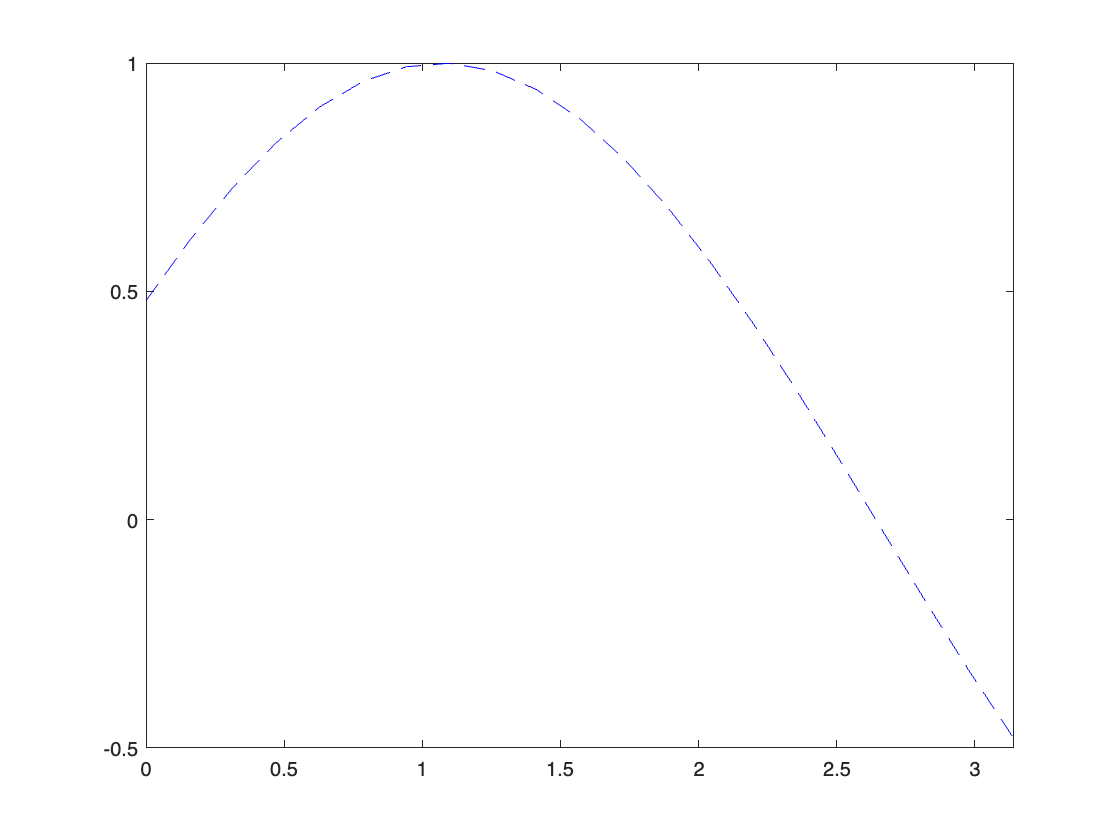

y1 = sin(x + 0.5);
plot(x, y1, 'b--');
xlim([0, pi]);

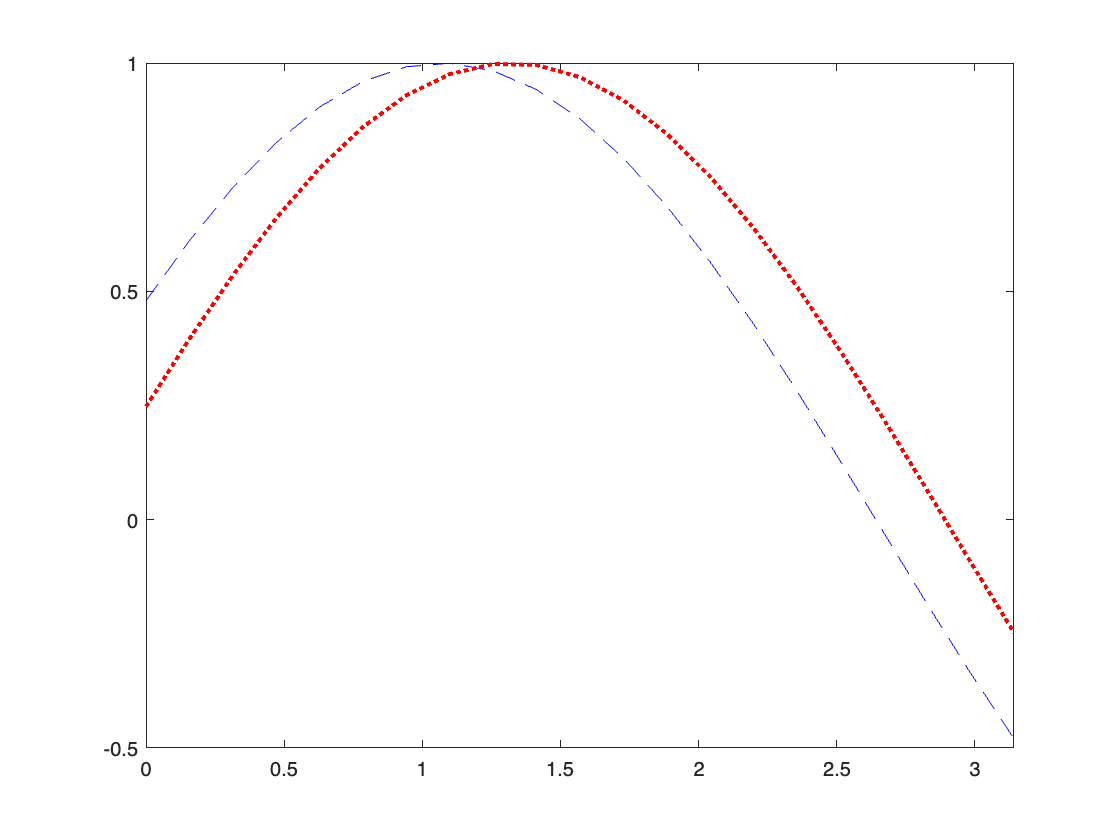

hold on
y2 = sin(x + 0.25);
plot(x, y2, 'r:', 'LineWidth', 2);

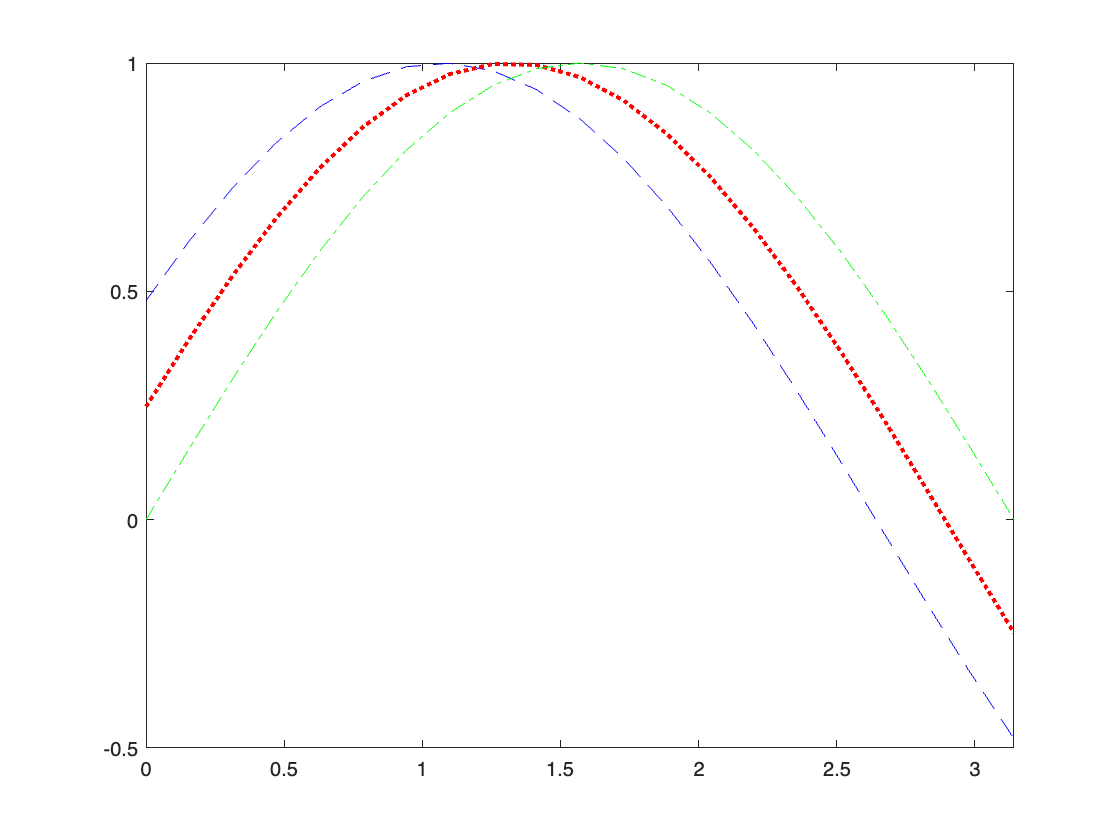

y3 = sin(x);
plot(x, y3, 'g-.');

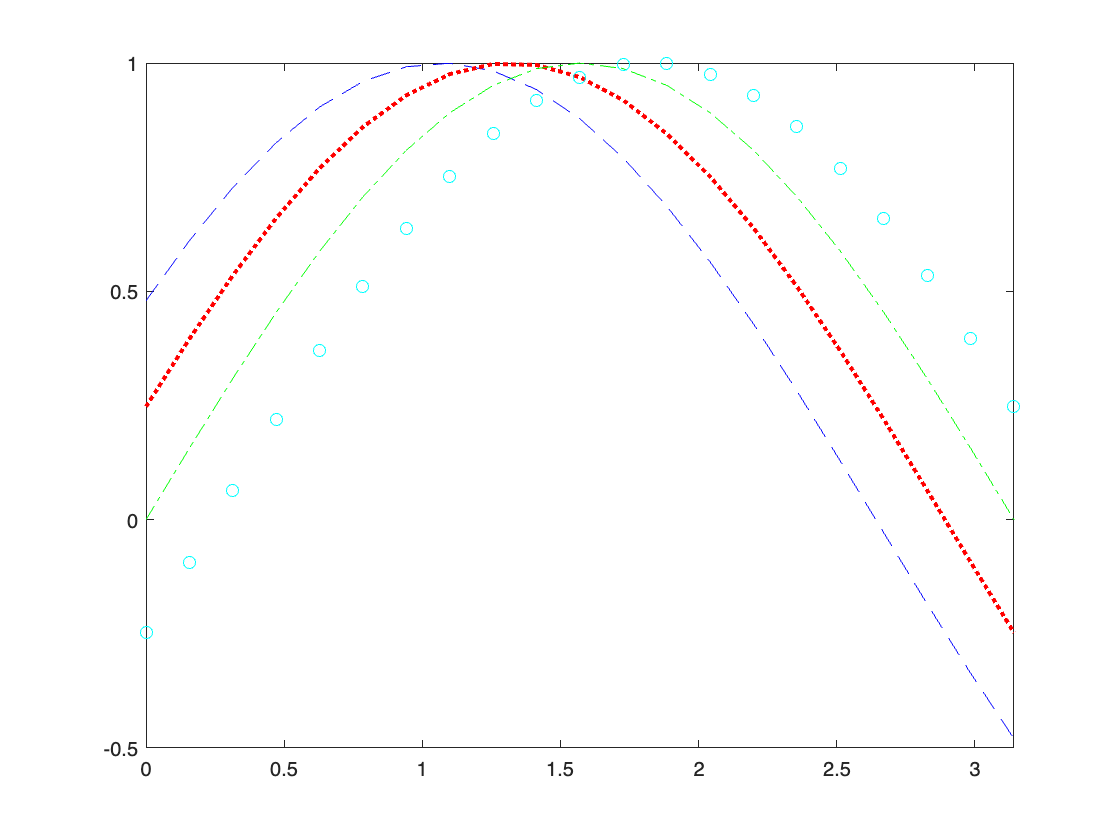

y4 = sin(x - 0.25);
plot(x, y4, 'co');

y5 = sin(x - 0.5);
plot(x, y5, '-ms', 'MarkerSize', 8, ...
    'MarkerEdgeColor', 'y', 'MarkerFaceColor', 'k');

Finally, use the "`hold off" command to turn off holding.`

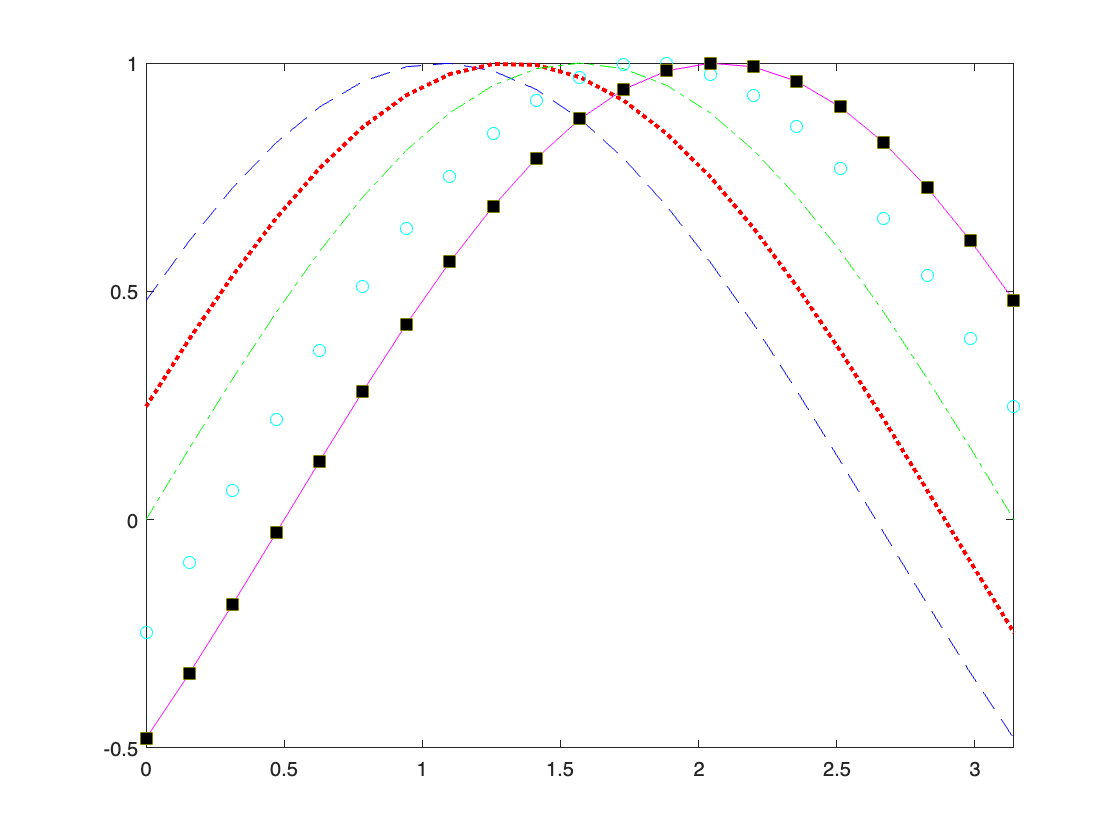

hold off

We can print a figure or save it to a specific file format using the `print` function. For example, to save into an SVG file, use the following command:

print myplot.svg -dsvg

The `-d<format>` specifies the format type. The SVG file uses vector graphics, preferred over bitmap images (see later) for plots. 

Other popular vector graphics formats include `eps`, and pdf. Note that to print in `eps`, we should specify `-depsc` instead of `-deps`:

print myplot.eps -depsc

If you print into a PDF file, the output is a full-page PDF, and you can crop the image to remove the white margins using some online tools that support autocrop.

MATLAB offers another wrapper of the `print` function, called `saveas`, for which we need to pass in a figure handle as the first argument. The handle to the current figure is `gcf`. The preceding two `print` statements are equivalent to the following:

saveas(gcf, 'myplot', 'svg');
saveas(gcf, 'myplot', 'epsc');

An advantage of `saveas` over `print` is that you can save into MATLAB's native `fig` format, which can then be loaded back in for manipulation.

We can divide a figure into an $m$-by-$n$ grid and creates axes in the position specified by $p$ with the function `subplot(m, n, p). `MATLAB numbers subplot positions by row.

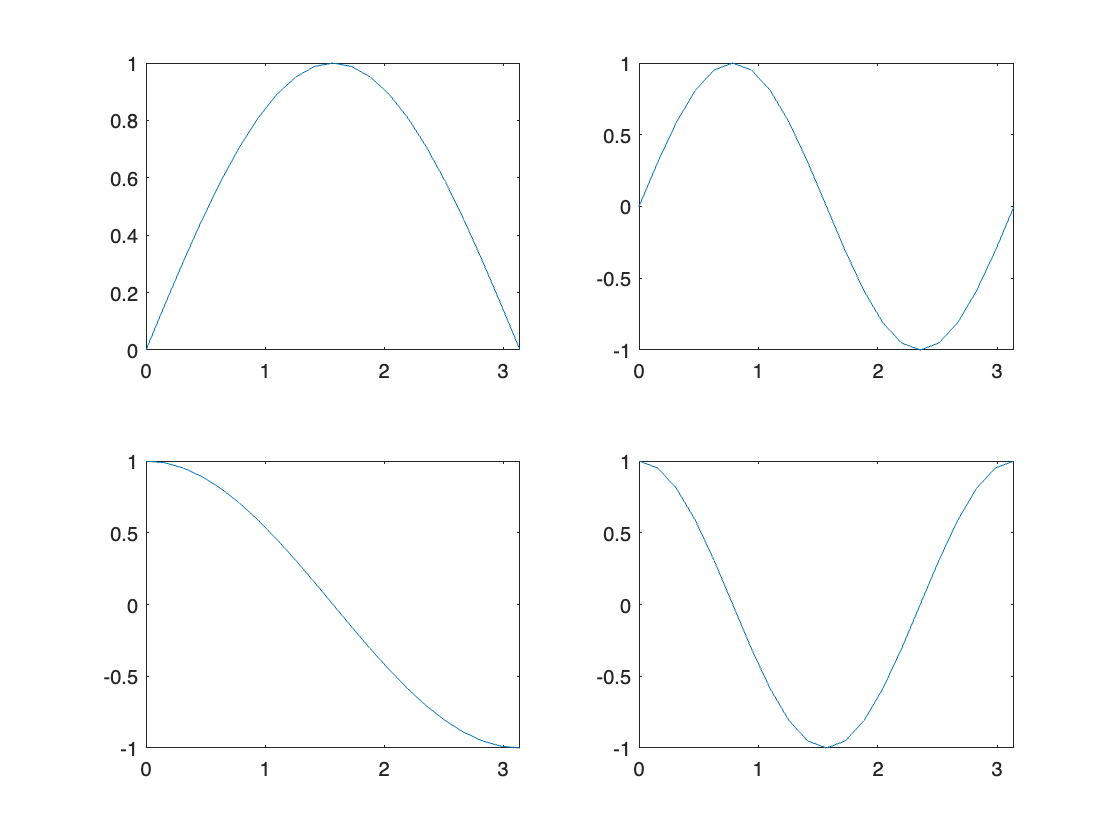

subplot(2, 2, 1);
plot(x, sin(x));
subplot(2, 2, 2);
plot(x, sin(2 * x));
subplot(2, 2, 3);
plot(x, cos(x));
subplot(2, 2, 4);
plot(x, cos(2 * x));

The `plot` function uses linear scales for both `x` and `y`. We can use `loglog` to plot in base-10 logarithmic scale in both $x$ and $y$.

x = 0 : 0.1 : 1

x =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000


y = 2 * x .^ 3

y =          0    0.0020    0.0160    0.0540    0.1280    0.2500    0.4320    0.6860    1.0240    1.4580    2.0000


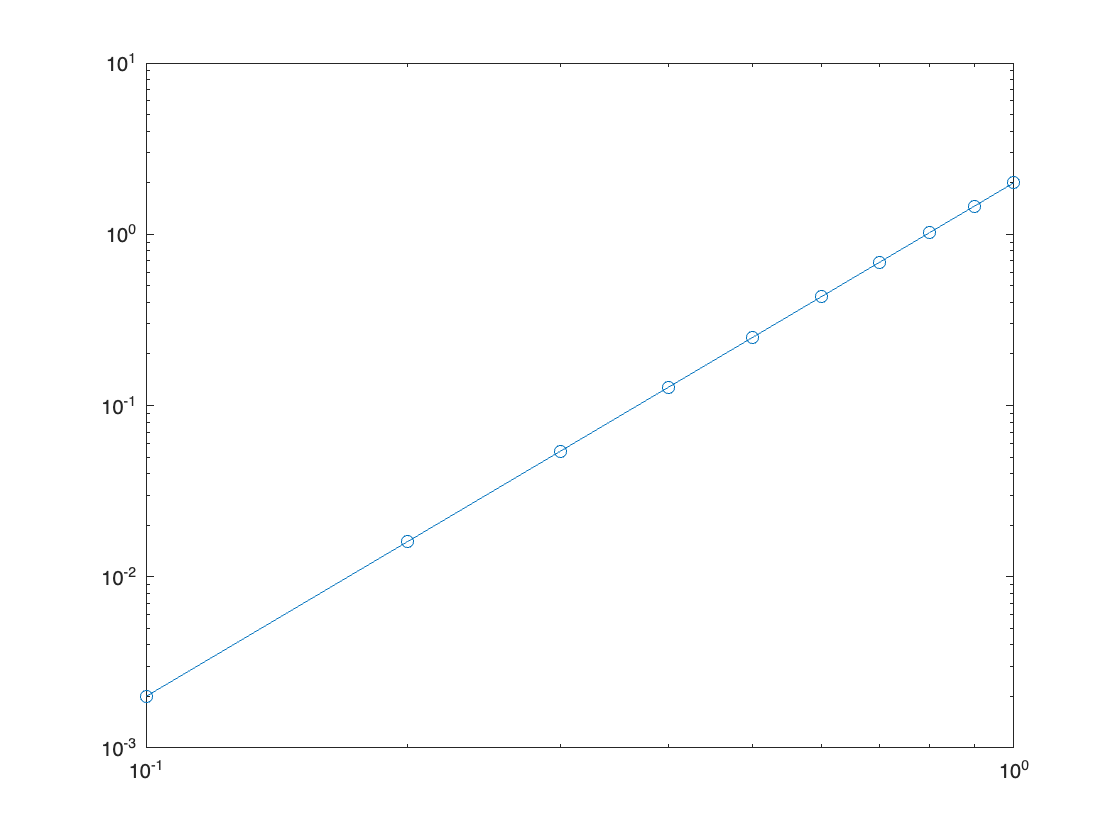

figure;
loglog(x, y, '-o');

Other commonly used functions are `semilogx` and `semilogy`, which use base-10 logarithmic scale in only $x$ and $y$, respectively, while using linear scale for the other axis.

x = 0 : 0.1 : 1

x =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000


y = 2 * x .^ 3

y =          0    0.0020    0.0160    0.0540    0.1280    0.2500    0.4320    0.6860    1.0240    1.4580    2.0000


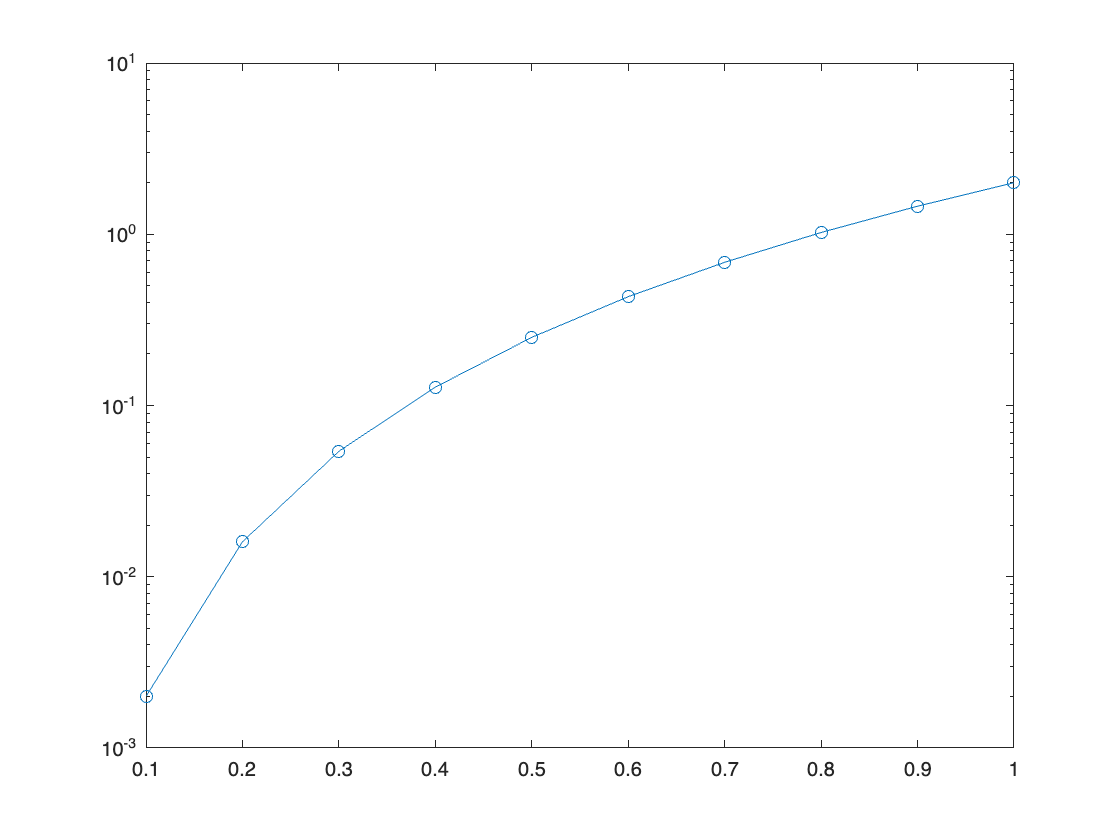

figure;
semilogy(x, y, '-o');

If we pass in a single input argument $y$ and $y$ is complex, then the `plot` function plots the imaginary part of $y$ versus the real part of $y$, such that `plot(y)` is equivalent to `plot(real(y),imag(y))`.

theta = pi / 20 : pi / 20 : 2 * pi

theta =     0.1571    0.3142    0.4712    0.6283    0.7854    0.9425    1.0996    1.2566    1.4137    1.5708    1.7279    1.8850    2.0420    2.1991    2.3562    2.5133    2.6704    2.8274    2.9845    3.1416    3.2987    3.4558    3.6128    3.7699    3.9270    4.0841    4.2412    4.3982    4.5553    4.7124    4.8695    5.0265    5.1836    5.3407    5.4978    5.6549    5.8119    5.9690    6.1261    6.2832


z = exp(1i * theta)

z =    0.9877 + 0.1564i   0.9511 + 0.3090i   0.8910 + 0.4540i   0.8090 + 0.5878i   0.7071 + 0.7071i   0.5878 + 0.8090i   0.4540 + 0.8910i   0.3090 + 0.9511i   0.1564 + 0.9877i   0.0000 + 1.0000i  -0.1564 + 0.9877i  -0.3090 + 0.9511i  -0.4540 + 0.8910i  -0.5878 + 0.8090i  -0.7071 + 0.7071i  -0.8090 + 0.5878i  -0.8910 + 0.4540i  -0.9511 + 0.3090i  -0.9877 + 0.1564i  -1.0000 + 0.0000i  -0.9877 - 0.1564i  -0.9511 - 0.3090i  -0.8910 - 0.4540i  -0.8090 - 0.5878i  -0.7071 - 0.7071i  -0.5878 - 0.8090i  -0.4540 - 0.8910i  -0.3090 - 0.9511i  -0.1564 - 0.9877i  -0.0000 - 1.0000i   0.1564 - 0.9877i   0.3090 - 0.9511i   0.4540 - 0.8910i   0.5878 - 0.8090i   0.7071 - 0.7071i   0.8090 - 0.5878i   0.8910 - 0.4540i   0.9511 - 0.3090i   0.9877 - 0.1564i   1.0000 - 0.0000i


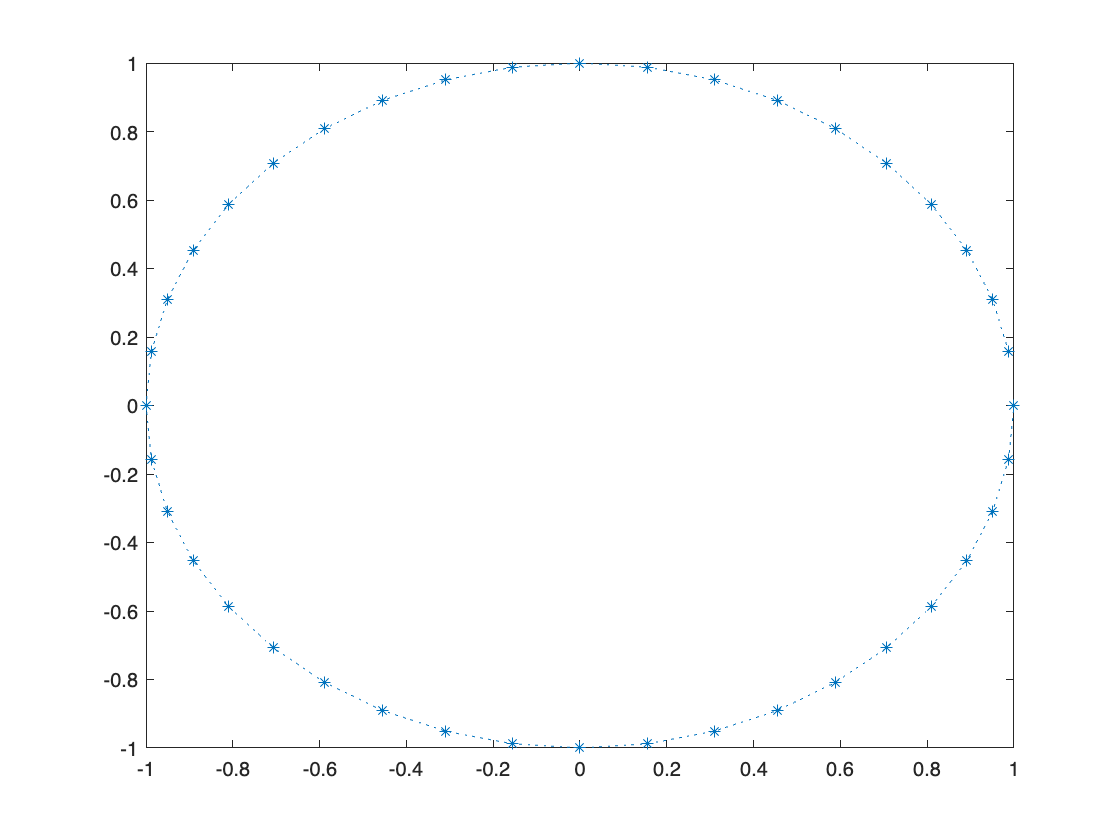

plot(z, ':*');

The plot is supposed to be a circle, but it is skewed. We can fix the aspect ratio by using the `axis equal` command:

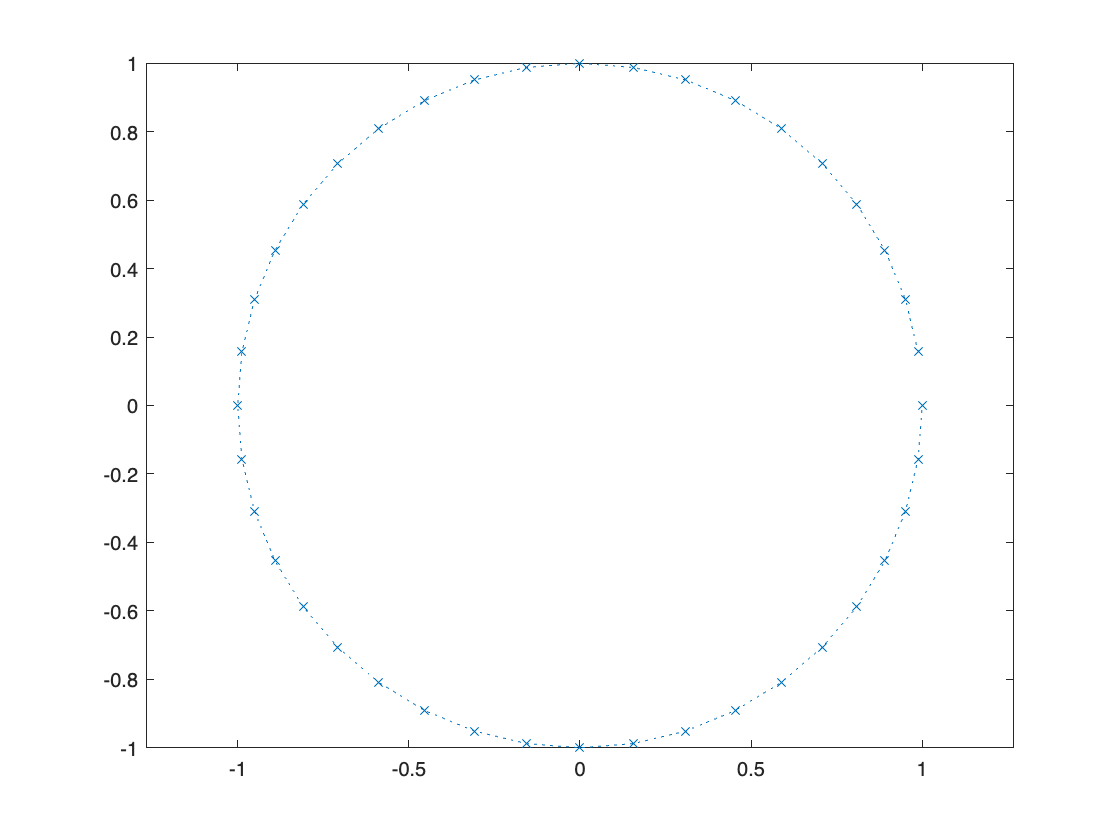

plot(z, ':x');
axis equal

We can also turn on the grid lines with the `grid on` command:

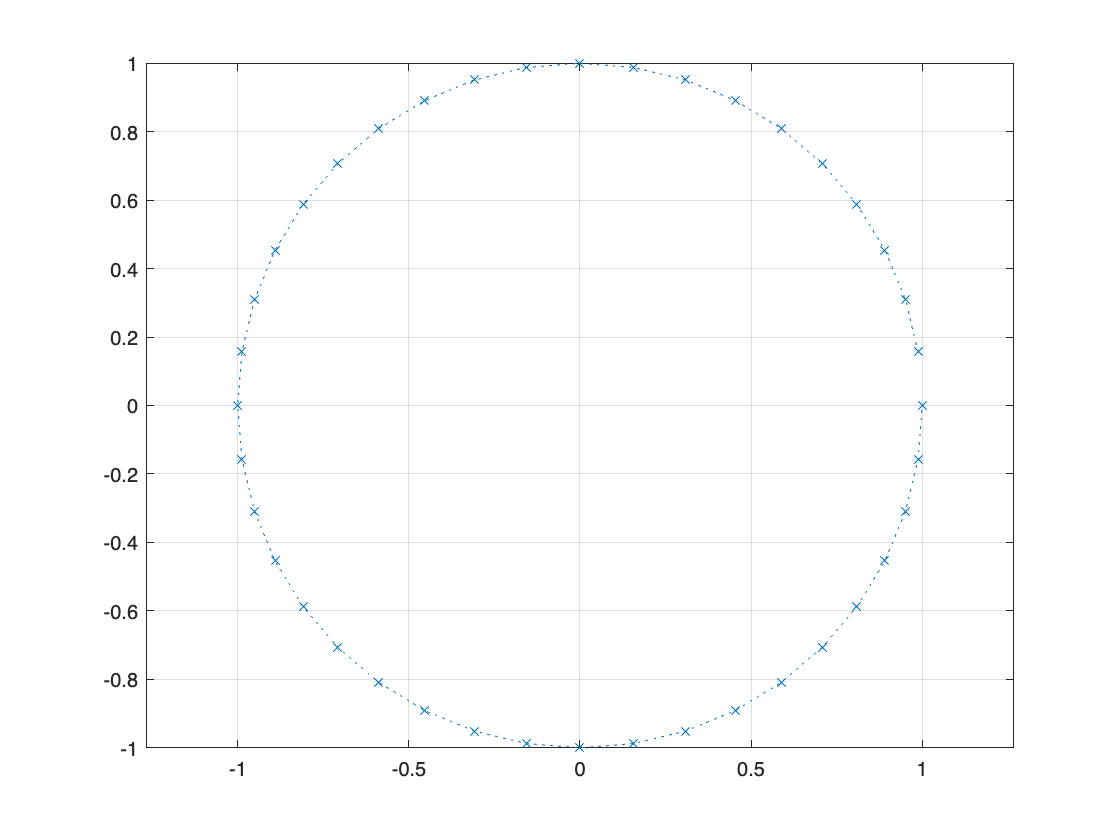

grid on

If we prefer a scattered plot instead of line plot, use the `scatter` command:

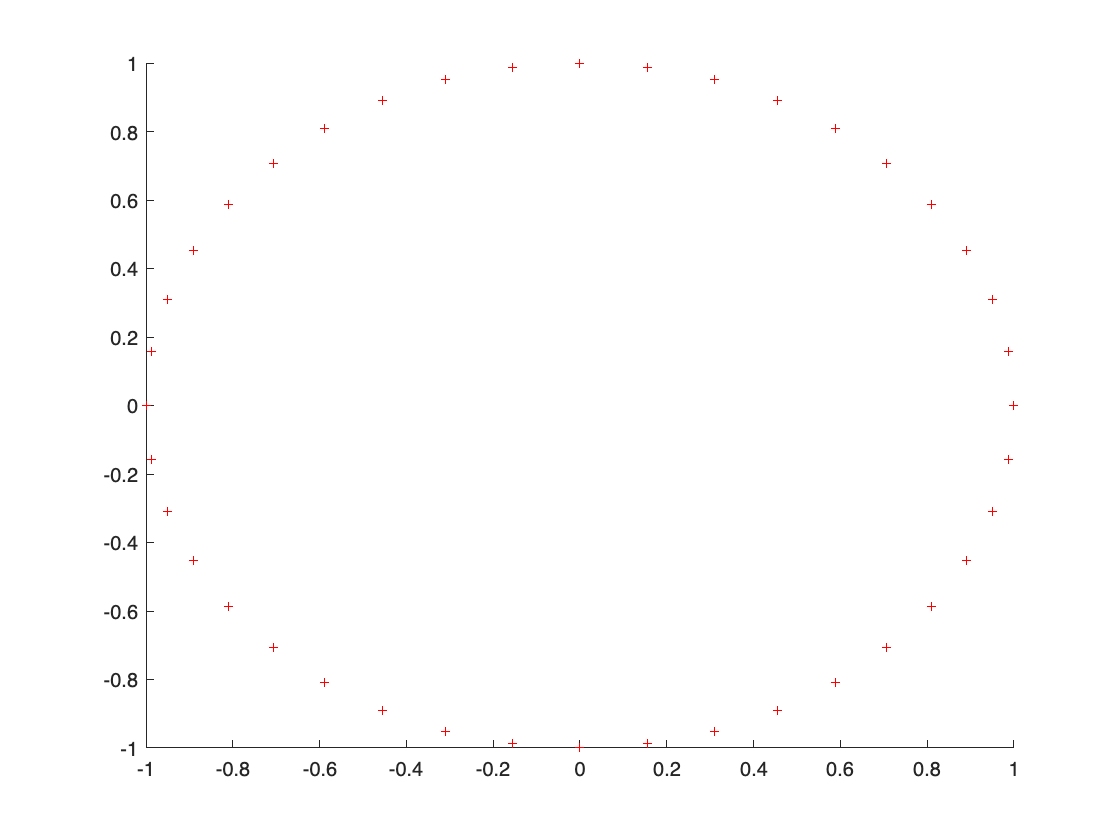

scatter(real(z), imag(z), 20, 'r+');

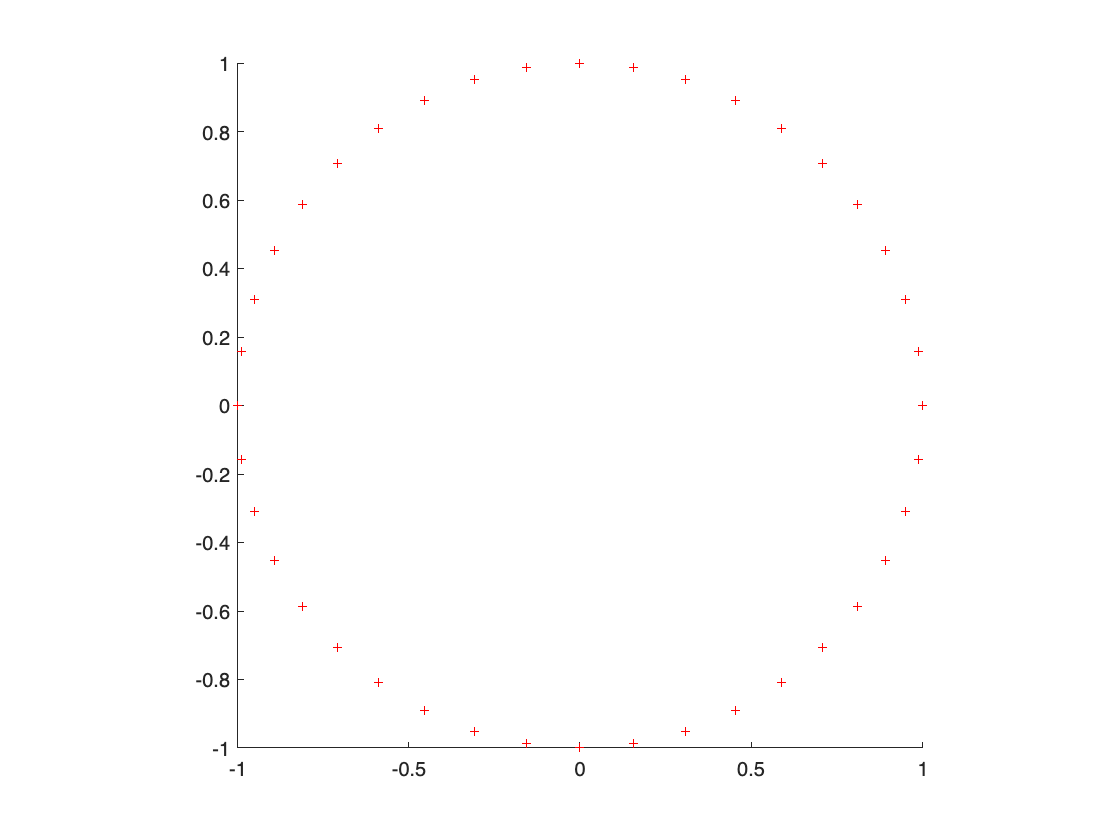

axis square

## Making a Movie

We can create a movie in MATLAB using `VideoWriter`.

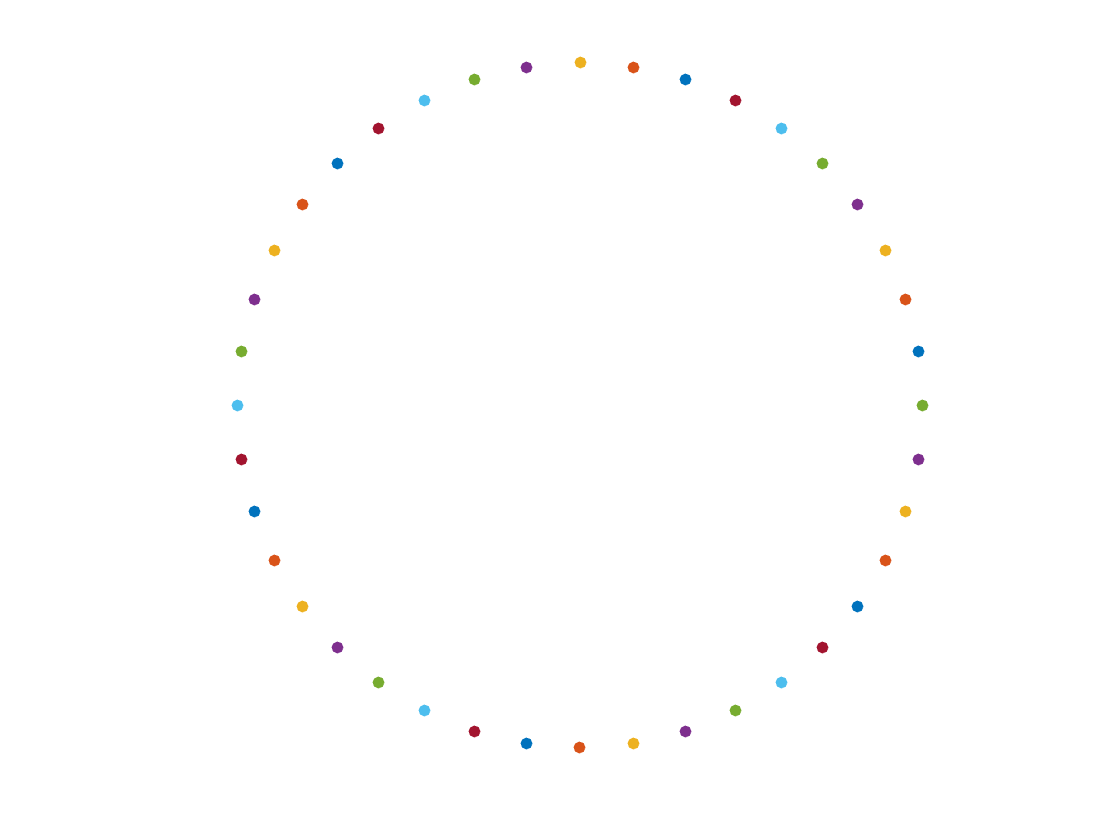

figure;
hold('on');
axis([-1, 1, -1, 1])
axis('square');
axis('manual');
axis('off');
video = VideoWriter('roots_of_unity.avi');
open(video);
for i = 1 : length(z)
    scatter(real(z(i)), imag(z(i)), 'filled');
    drawnow;
    writeVideo(video, getframe(gcf));
end
hold('off');

close(video);

## 3D Plotting

To make a 3D scattered plot, use the `scatter3` function.

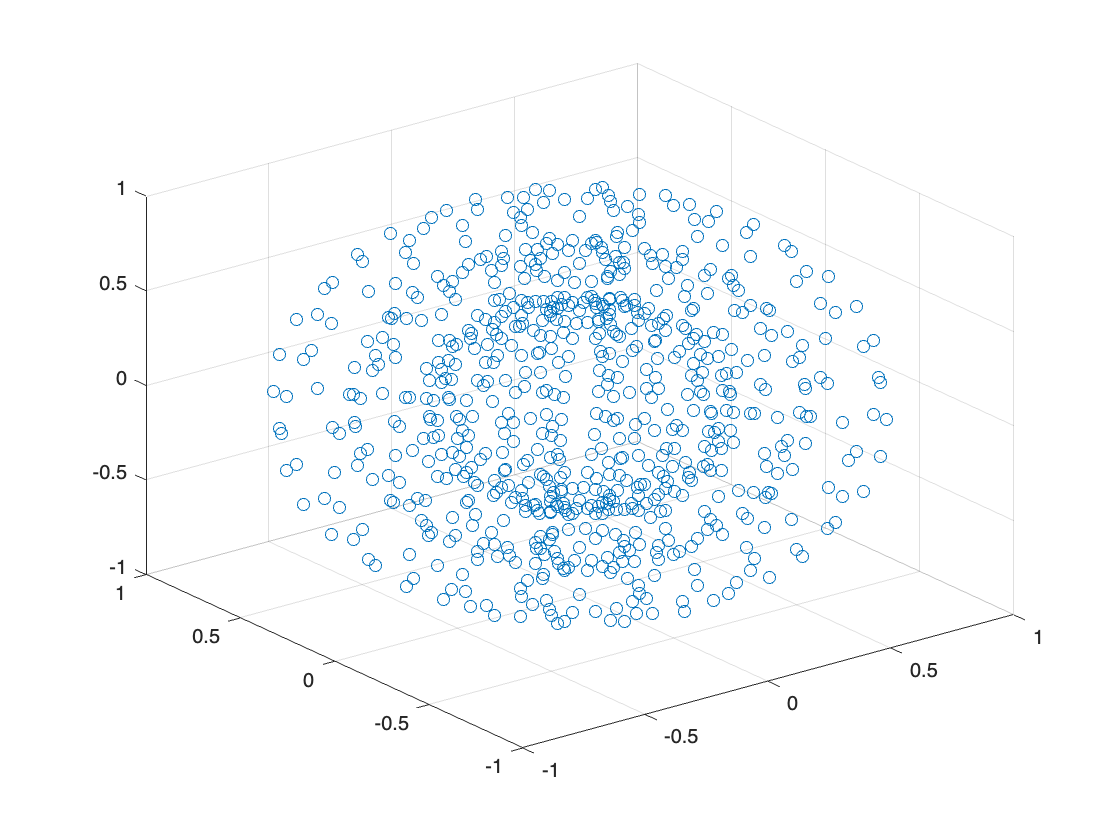

figure
[X,Y,Z] = sphere(16);
x = [0.5*X(:); 0.75*X(:); X(:)];
y = [0.5*Y(:); 0.75*Y(:); Y(:)];
z = [0.5*Z(:); 0.75*Z(:); Z(:)];
scatter3(x,y,z)

We can draw meshes, surfaces, and contours in 3D.

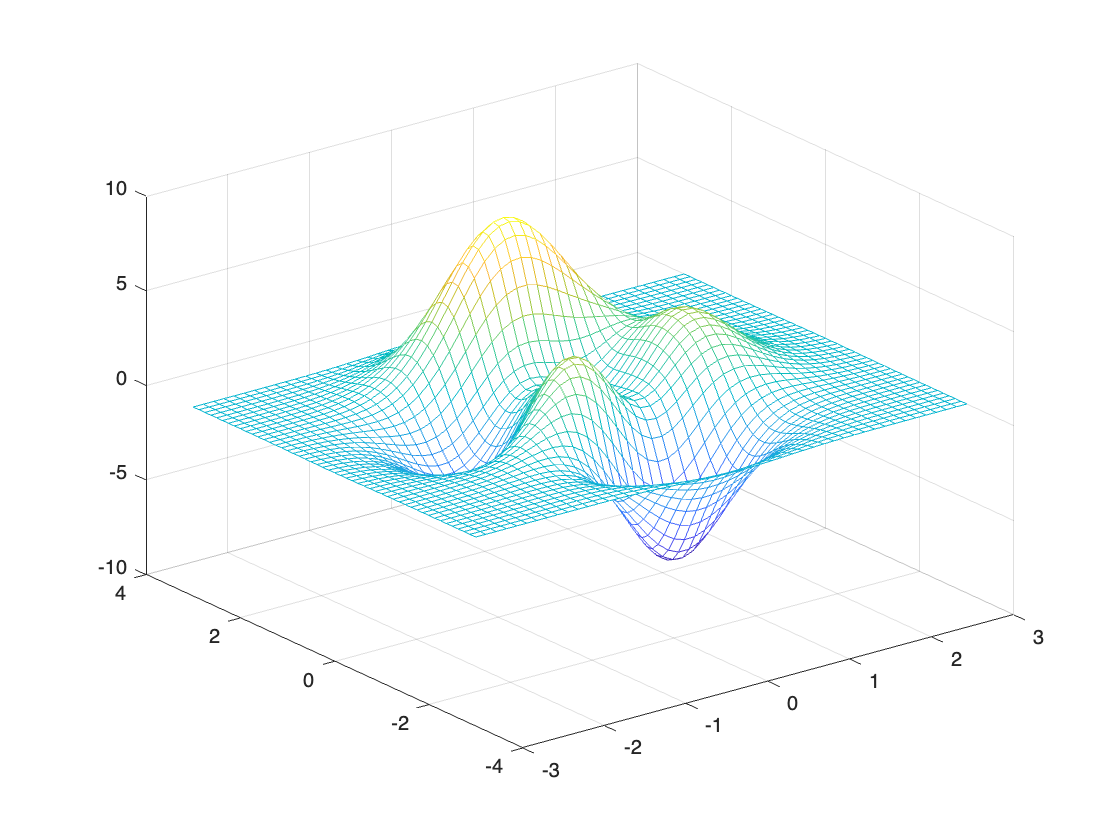

[X, Y, Z] = peaks;
mesh(X, Y, Z);

surf(X, Y, Z);

We can specify a color map with a colorbar.

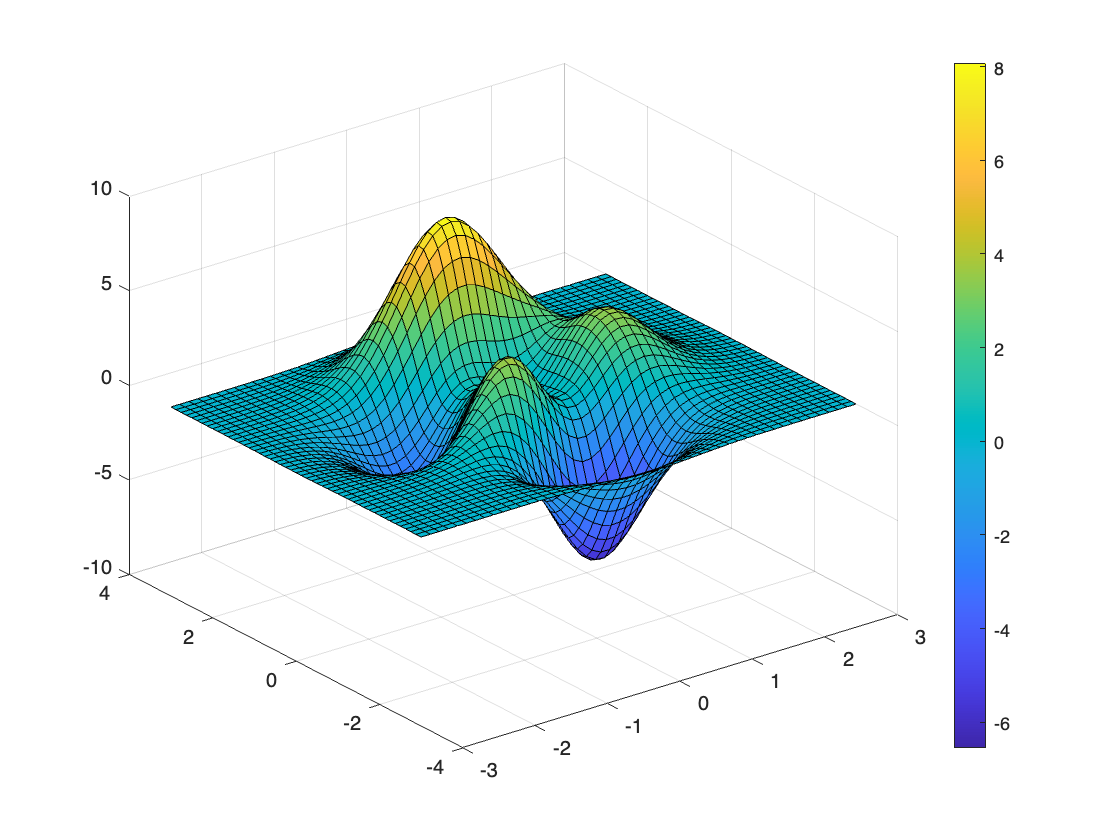

colormap('parula');
colorbar;

We can specify different shading and lighting for the 3D plots.

surf(X, Y, Z);
shading('interp');

We can overlay countours with the surface.

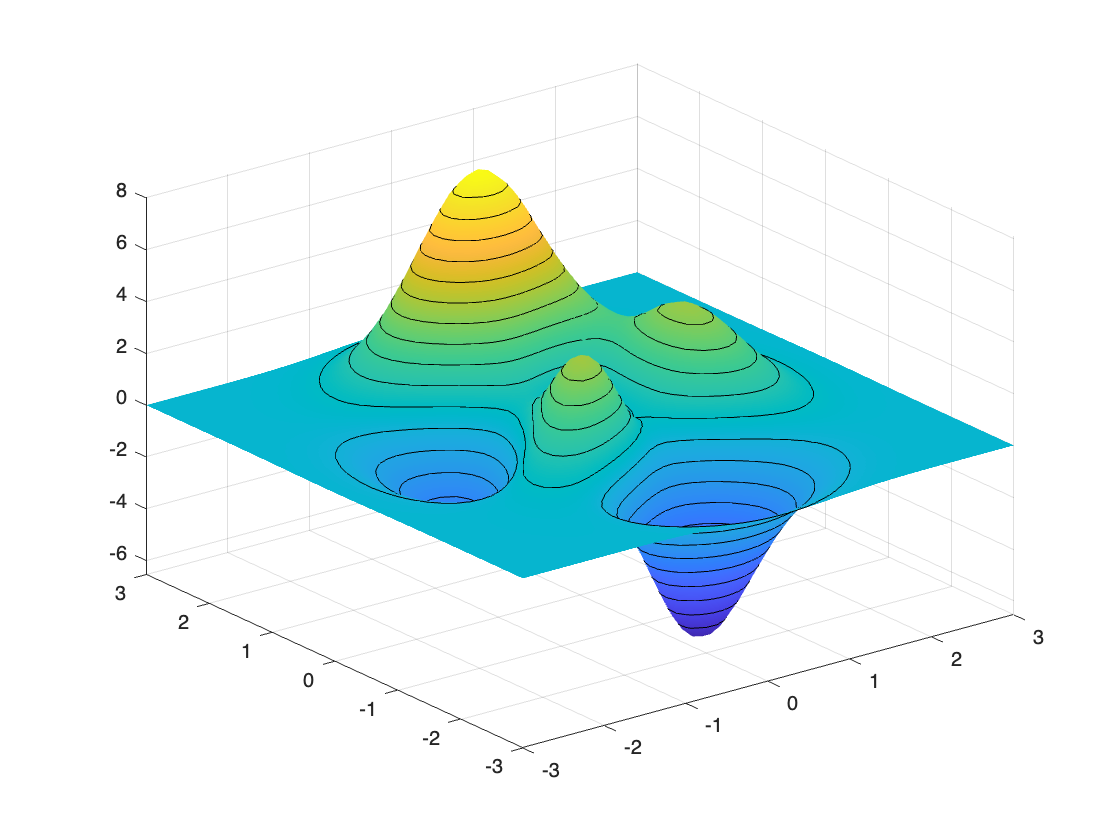

hold('on');
contour3(X, Y, Z, 20, 'k');
hold('off');

We can also specify lighting for more beutiful rendering.

surf(X, Y, Z, 'FaceColor', 'b', 'EdgeColor', 'none');
camlight('left');
lighting('gouraud');

Finally, to save a 3D image, it is better to use a bigmap-image format, such as PNG, instead of vector graphics. We can save the image to a PNG file using the following command:

print surfplot.png -dpng

or 

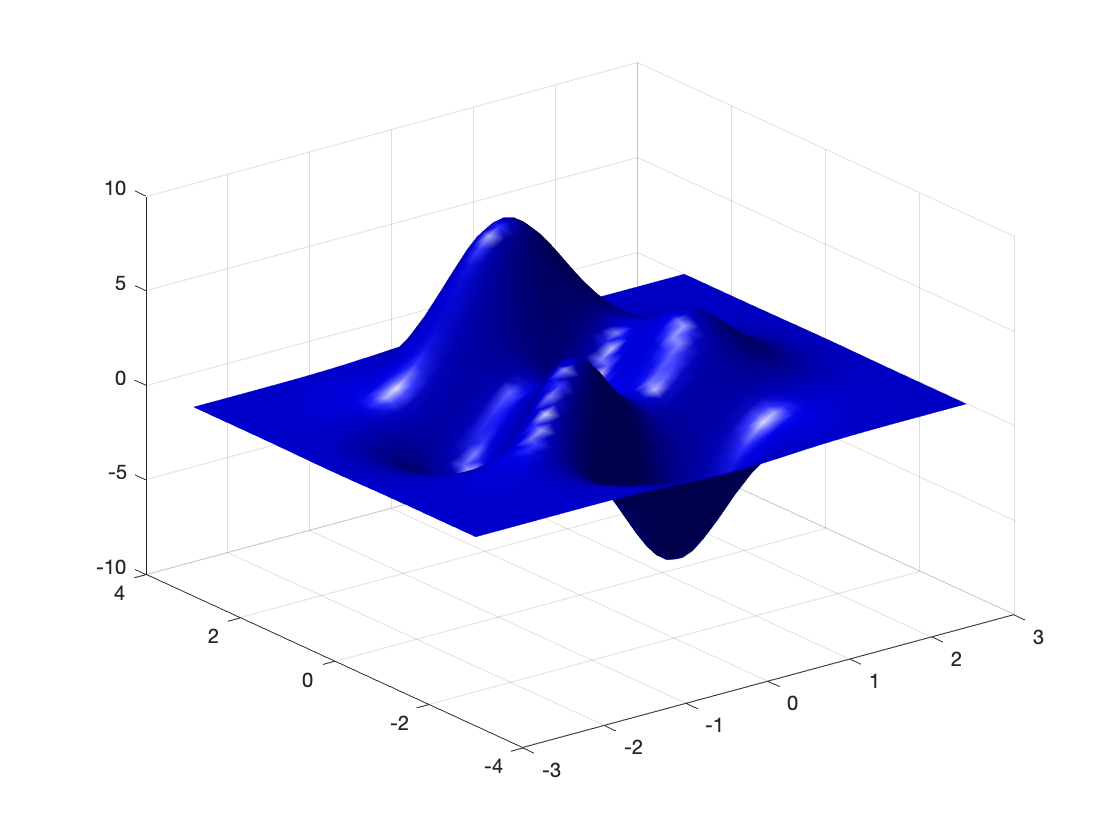

saveas(gcf, 'myplot.png', 'png')

PNG is a bitmap image with lossless compression, which is preferable over lossy-compression images (such as JPEG), unless the image is very large.